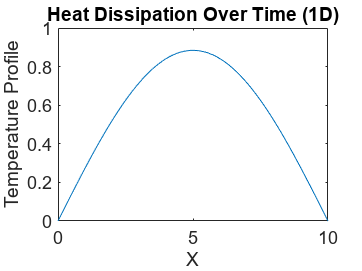

M1D =                    0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0              

format long;
close all;
clf;

% 1-D example input
IC1D = @(x, l)    sin(x*pi/l);
h = 0.01;
k = 0.0001;
x_lim = 10;
alpha = 0.5;
t = 5;
N = (x_lim./h)+1;

M1D = FD_crank_nicolson_1D (IC1D, N, h, k, x_lim, alpha, t)


return



function M = FD_crank_nicolson_1D (f, N, h, k, x_lim, alpha, t)
% 1-D implementation 
M = zeros(floor(N),floor(t/k));
x = 0:h:x_lim;
M(:, 1) = (f(x, x_lim))';
pause (0.1)

%for homogeneous boundary condition.
a = alpha^2*k;
b = 2*h^2+2*alpha^2*k;
c = 2*h^2-2*alpha^2*k;


% Populate 2-D matrix
for j = 1:t/k-1
    e = ones(N,1);
    A = spdiags([-a*e b*e -a*e],-1:1,N-2,N-2);
    B = a*M(1:(end-2),j)+c*M(2:(end-1),j)+a*M(3:end,j);
    u = A\B;
    M(2:end-1,j+1) = u;
end

% Animation code
for i = 1:100:t/k
    plot (x, M(:, i));
    axis([0 x_lim 0 1])
    xlabel('X')
    ylabel('Temperature Profile')
    title('Heat Dissipation Over Time (1D)')
    pause(0.01)
end
end

